clc;
clear;
runtimea=40;
for counta=1:runtimea
car_number   = counta*2
Xcar_number(counta)=car_number;
runtime=40;
for count=1:runtime
Road_length  =100;
acceleration = 2+0.2*count;
deceleration =-6.5;
a_d(count)=acceleration/Road_length;
%initial speed
u = 5;
%time limitis
time =1000;
%limit speed
lim = 15;

%repeat loop
for l=1:10
%initial position of car
J = 1:car_number;
A = rand(1,car_number).*Road_length;
x(J,1) =sort(A);
v(J,1)=u;
%minimum distance between cars
x0 = Road_length/car_number;
num = car_number-1;
delT = 0.1;
k = time / delT;
%
average(1) = 0;
t(1) = 0;

for T=2:k
    for J=1:car_number
        if J == car_number
            if J==1
                dis(J,T)= Road_length;
            else
                dis(J,T) = x(1,T-1)-x(J,T-1);
            end
        else
            dis(J,T) = x(J+1,T-1)-x(J,T-1);
        end
        if dis(J,T)<0
            dis(J,T) = Road_length+dis(J,T);
        end
        if dis(J,T) > acceleration * delT
           v(J,T)=v(J,T-1) + acceleration * delT;
        elseif dis(J,T) <= v(J,T-1)
            dis(J,T)=0;
            v(J,T)=0;
        else
           v(J,T)=v(J,T-1)+ deceleration * delT;
        end
        if v(J,T)<0
            v(J,T)=0;
        end
        if v(J,T)>lim
            v(J,T)=lim;
        end
        delta_dis(J,T)=v(J,T)*delT;
        if delta_dis(J,T)>dis(J,T);
            delta_dis(J,T)=dis(J,T);
            v(J,T)=dis(J,T);
        end
        x(J,T)=x(J,T-1)+delta_dis(J,T);
        if x(J,T) > Road_length
           x(J,T)=x(J,T)- Road_length;
        end
    end
      max_speed(T) = max(v(J,T));
      min_speed(T) = min(v(J,T));
      average(T) = sum(v(:,T)) / car_number;
      t(T) = t(T-1) + delT;
end
t(T) = t(T);
x(J,T)=x(J,T);
v(J,T)=v(J,T);
average(T) = average(T);
k_1 = floor(k/2);
d_av = average(1,(k_1):k);
m(l) = mean(d_av);
end
averagespeed(counta,count) = mean(m);
%percentage
end
end

car_number = 2

car_number = 4

car_number = 6

car_number = 8

car_number = 10

car_number = 12

car_number = 14

car_number = 16

car_number = 18

car_number = 20

car_number = 22

car_number = 24

car_number = 26

car_number = 28

car_number = 30

car_number = 32

car_number = 34

car_number = 36

car_number = 38

car_number = 40

car_number = 42

car_number = 44

car_number = 46

car_number = 48

car_number = 50

car_number = 52

car_number = 54

car_number = 56

car_number = 58

car_number = 60

car_number = 62

car_number = 64

car_number = 66

car_number = 68

car_number = 70

car_number = 72

car_number = 74

car_number = 76

car_number = 78

car_number = 80

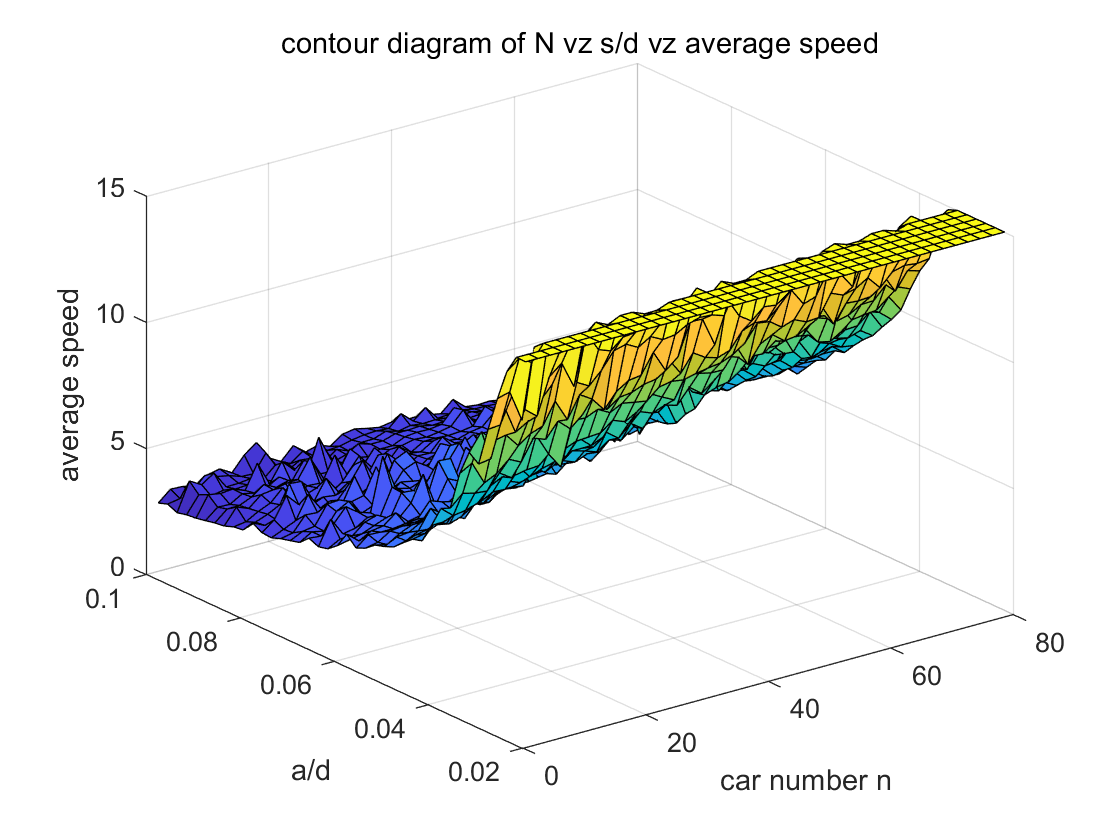


surf(Xcar_number, a_d,averagespeed)
title('contour diagram of N vz s/d vz average speed')
xlabel('car number n')
ylabel('a/d')
zlabel('average speed')